# Project MSB1015: Ayahuasca

## Script 5: PCA

## Guus Wilmink, i6156211

## Load data

clear all; close all;

% Add Fieldtrip toolbox
addpath('./fieldtrip-20220912');

% Load the data
load('.\processed_1_30Hz.mat');
load('.\processed_30_100Hz.mat');
elec = load(".\freqs_1-30Hz.mat").data_all_mean.elec;

% Specify bands
delta=2.5; theta=6; alpha=10.5; beta=21.5; slowgamma=40; fastgamma=75;

**Select frequency band or all frequencies**

band = fastgamma;       % Frequency band

% Prepare data
if length(band) == 1
    data = zeros(6,16,63);
elseif length(band) == 30
    data = zeros(6,16,63,30);
else
    data = zeros(6,16,63,15);
end
for trial = 1:6
    if band == delta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,1));
    end
    if band == theta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,2));
    end
    if band == alpha
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,3));
    end
    if band == beta
        data(trial,:,:) = squeeze(processed_1_30Hz{trial}.powspctrm_b(:,:,4));
    end
    if band == slowgamma
        data(trial,:,:) = squeeze(processed_30_100Hz{trial}.powspctrm_b(:,:,1));
    end
    if band == fastgamma
        data(trial,:,:) = squeeze(processed_30_100Hz{trial}.powspctrm_b(:,:,2));
    end
    if length(band) == 30
        data(trial,:,:,:) = processed_1_30Hz{trial}.powspctrm;
    end
    if length(band) == 15
        data(trial,:,:,:) = processed_30_100Hz{trial}.powspctrm;
    end
end

## **PCA over subjects**

One per trial

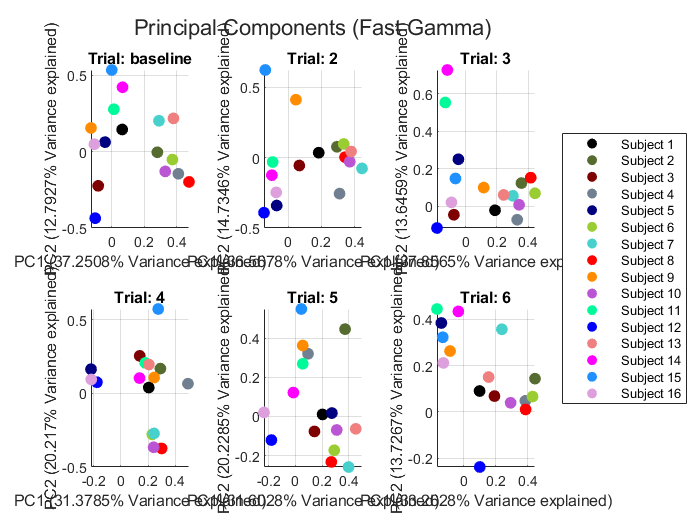

leg =   Legend (Subject 1, Subject 2, Subject 3, Subject 4, Subject 5, Subject 6, Subject 7, Subject 8, Subject 9, Subject 10, Subject 11, Subject 12, Subject 13, Subject 14, Subject 15, Subject 16) with properties:

         String: {'Subject 1'  'Subject 2'  'Subject 3'  'Subject 4'  'Subject 5'  'Subject 6'  'Subject 7'  'Subject 8'  'Subject 9'  'Subject 10'  'Subject 11'  'Subject 12'  'Subject 13'  'Subject 14'  'Subject 15'  'Subject 16'}
       Location: 'layout'
    Orientation: 'vertical'
       FontSize: 7.6500
       Position: [0.8027 0.2312 0.1782 0.5150]
          Units: 'normalized'

  Show all properties


rpt_PCA = []; % Pre-assign structure
rng(0); % Set rng for reproducible results
col = [0 0 0; 0.3333 0.4196 0.1843; 0.4980 0 0; 0.4392 0.5020 0.5647; 0 0 0.5020; 0.6039 0.8039 0.1961; 0.2824 0.8196 0.8000; 1 0 0; 1 0.5490 0; 0.7294 0.3333 0.8275; 0 0.9804 0.6039; 0 0 1; 0.9412 0.5020 0.5020; 1 0 1; 0.1176 0.5647 1; 0.8667 0.6257 0.8667];

% Compute and plot PCAs
for trial=1:6
    temp                                       = squeeze(data(trial,:,:))';
    [coeff,score,latent,tsquared,explained,mu] = pca(temp); % Compute PCAs
    rpt_PCA{trial}.coeff                       = coeff;     % Add coefficients to cell
    rpt_PCA{trial}.score                       = score;     % Add scores to cell
    rpt_PCA{trial}.latent                      = latent;    % Add PC variance
    rpt_PCA{trial}.tsquared                    = tsquared;  % Add Hotelling's t-squared
    rpt_PCA{trial}.explained                   = explained; % Add explained variance
    rpt_PCA{trial}.mu                          = mu;        % Add mean estimate of each variable
end

% Plot PCAs
figure; tcl=tiledlayout(2,3);
for trial=1:6
    nexttile
    hold on
    for subj=1:16
        scatter(rpt_PCA{trial}.coeff(subj,1), rpt_PCA{trial}.coeff(subj,2), 50, col(subj,:), 'filled')
    end
    if trial == 1
        title('Trial: baseline')
    else
        title(['Trial: ' num2str(trial)])
    end
    xlabel(['PC1 (' num2str(rpt_PCA{trial}.explained(1)) '% Variance explained)'])
    ylabel(['PC2 (' num2str(rpt_PCA{trial}.explained(2)) '% Variance explained)'])
    if band == delta
        sgtitle('Principal Components (Delta')
    elseif band == theta
        sgtitle('Principal Components (Theta)')
    elseif band == alpha
        sgtitle('Principal Components (Alpha)')
    elseif band == beta
        sgtitle('Principal Components (Beta)')
    elseif band == slowgamma
        sgtitle('Principal Components (Slow Gamma)')
    else
        sgtitle('Principal Components (Fast Gamma)')
    end
    grid on
end
leg = legend('Subject 1', 'Subject 2', 'Subject 3', 'Subject 4', 'Subject 5', 'Subject 6', 'Subject 7', 'Subject 8', 'Subject 9', 'Subject 10', 'Subject 11', 'Subject 12', 'Subject 13', 'Subject 14', 'Subject 15', 'Subject 16');
leg.Layout.Tile = 'East'

## **PCA over trials**

One per subject

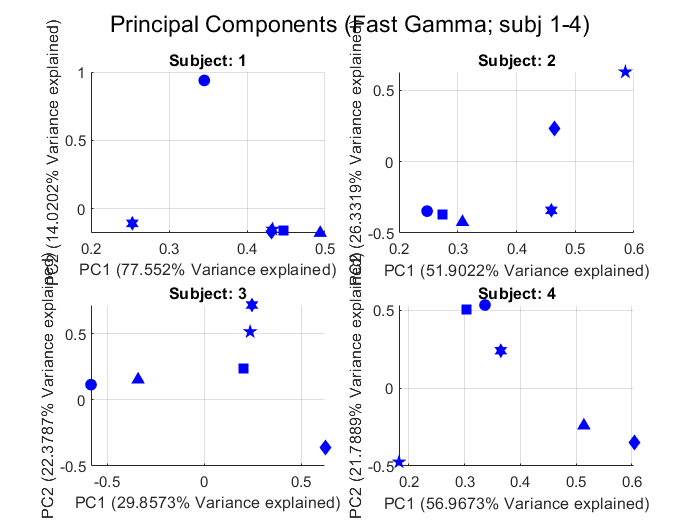

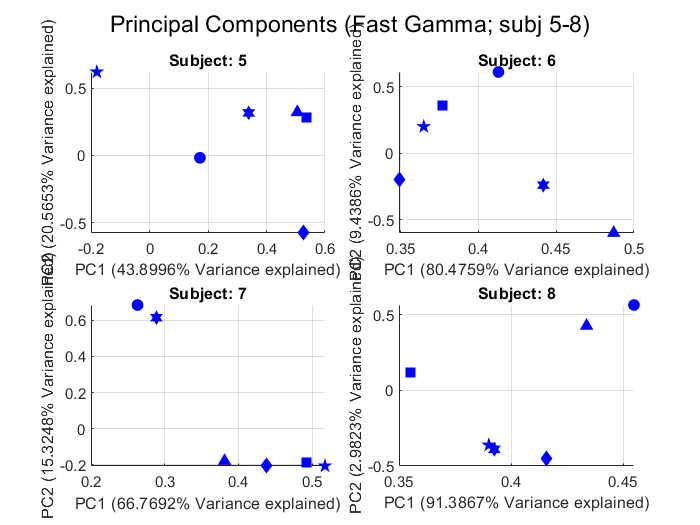

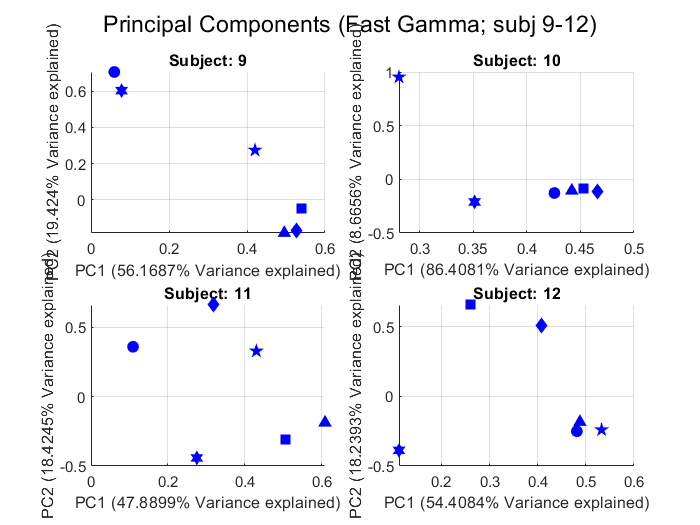

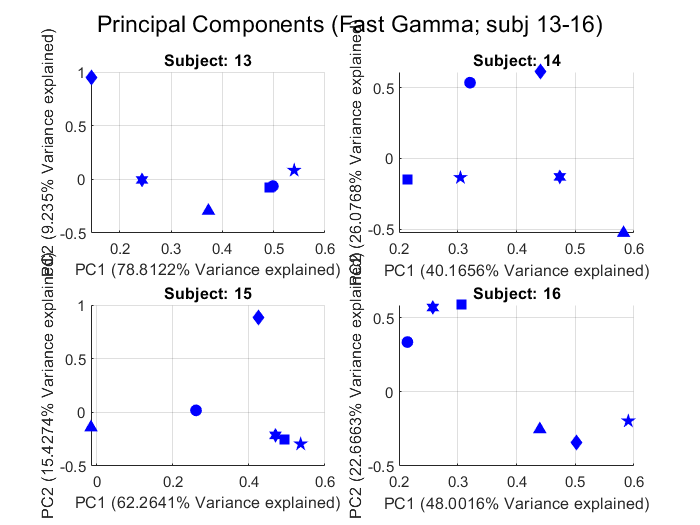

subj_PCA = []; % Pre-assign structure
rng(0); % Set rng for reproducible results
markers={'o','square','^','diamond','pentagram','hexagram'}; % Set marker styles
sizes=[50 70 50 50 90 80];

% Compute and plot PCAs
for subj=1:16
    temp                                       = squeeze(data(:,subj,:))';
    [coeff,score,latent,tsquared,explained,mu] = pca(temp);                 % Compute PCAs
    subj_PCA{subj}.coeff                       = coeff;                     % Add coefficients to cell
    subj_PCA{subj}.score                       = score;                     % Add scores to cell
    subj_PCA{subj}.latent                      = latent;                    % Add PC variance
    subj_PCA{subj}.tsquared                    = tsquared;                  % Add Hotelling's t-squared
    subj_PCA{subj}.explained                   = explained;                 % Add explained variance
    subj_PCA{subj}.mu                          = mu;                        % Add mean estimate of each variable
end

% Plot PCAs
for subj=1:16
    if ismember(subj, 1:4:13)
        figure;
    end
    if ismember(subj, 1:4)
        subplot(2,2,subj)
        if band == delta
            sgtitle('Principal Components (Delta; subj 1-4)')
        elseif band == theta
            sgtitle('Principal Components (Theta; subj 1-4)')
        elseif band == alpha
            sgtitle('Principal Components (Alpha; subj 1-4)')
        elseif band == beta
            sgtitle('Principal Components (Beta; subj 1-4)')
        elseif band == slowgamma
            sgtitle('Principal Components (Slow Gamma; subj 1-4)')
        else
            sgtitle('Principal Components (Fast Gamma; subj 1-4)')
        end
    elseif ismember(subj, 5:8)
        subplot(2,2,(subj-4))
        if band == delta
            sgtitle('Principal Components (Delta; subj 5-8)')
        elseif band == theta
            sgtitle('Principal Components (Theta; subj 5-8)')
        elseif band == alpha
            sgtitle('Principal Components (Alpha; subj 5-8)')
        elseif band == beta
            sgtitle('Principal Components (Beta; subj 5-8)')
        elseif band == slowgamma
            sgtitle('Principal Components (Slow Gamma; subj 5-8)')
        else
            sgtitle('Principal Components (Fast Gamma; subj 5-8)')
        end
    elseif ismember(subj, 9:12)
        subplot(2,2,(subj-8))
        if band == delta
            sgtitle('Principal Components (Delta; subj 9-12)')
        elseif band == theta
            sgtitle('Principal Components (Theta; subj 9-12)')
        elseif band == alpha
            sgtitle('Principal Components (Alpha; subj 9-12)')
        elseif band == beta
            sgtitle('Principal Components (Beta; subj 9-12)')
        elseif band == slowgamma
            sgtitle('Principal Components (Slow Gamma; subj 9-12)')
        else
            sgtitle('Principal Components (Fast Gamma; subj 9-12)')
        end
    else
        subplot(2,2,(subj-12))
        if band == delta
            sgtitle('Principal Components (Delta; subj 13-16)')
        elseif band == theta
            sgtitle('Principal Components (Theta; subj 13-16)')
        elseif band == alpha
            sgtitle('Principal Components (Alpha; subj 13-16)')
        elseif band == beta
            sgtitle('Principal Components (Beta; subj 13-16)')
        elseif band == slowgamma
            sgtitle('Principal Components (Slow Gamma; subj 13-16)')
        else
            sgtitle('Principal Components (Fast Gamma; subj 13-16)')
        end
    end
    hold on;
    for trial=1:6
        scatter(subj_PCA{subj}.coeff(trial,1), subj_PCA{subj}.coeff(trial,2), sizes(trial), 'b', markers{trial}, 'filled')
    end
    title(['Subject: ' num2str(subj)])
    xlabel(['PC1 (' num2str(subj_PCA{subj}.explained(1)) '% Variance explained)'])
    ylabel(['PC2 (' num2str(subj_PCA{subj}.explained(2)) '% Variance explained)'])
    grid on
end

## PCA for subject-trial pairs

Single plot with all trials of all subjects

Fistly the matrices are combined and transformed, so each row represents a subject-trial pair and each column a channel. Row 1-16 will be subject 1-16, trial 1; row 17-36 will be subject 1-16, trial 2; etc..

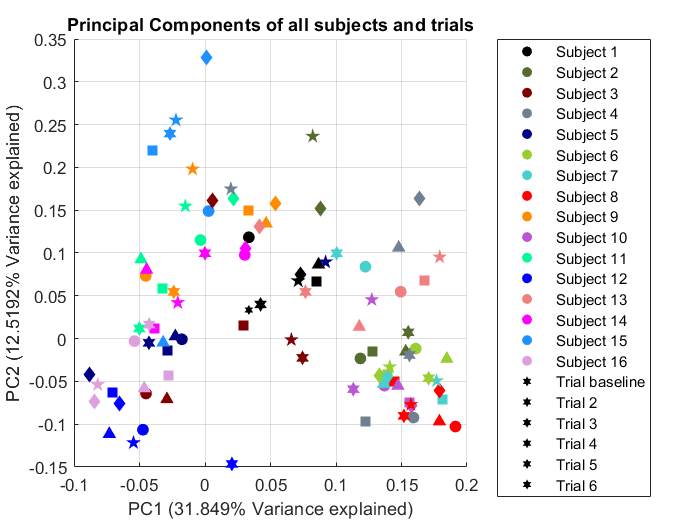

% Transform matrices into single matrix
transformed_data = zeros(96, 63);
for trial=1:6
    transformed_data((1+16*trial-16):(16*trial),:) = squeeze(data(trial,:,:));
end
transformed_data = transformed_data';

% Set colors
colors = repmat(col, 6, 1);

% Compute PCAs
[coeff,score,latent,tsquared,explained,mu] = pca(transformed_data);
rpt_subj_PCA.coeff                         = coeff;
rpt_subj_PCA.score                         = score;
rpt_subj_PCA.latent                        = latent;
rpt_subj_PCA.tsquared                      = tsquared;
rpt_subj_PCA.explained                     = explained;
rpt_subj_PCA.mu                            = mu;

% Dummy plotting for legend handles
figure; hold on;
for subj = 1:16
    scatter(rpt_subj_PCA.coeff(subj,1), rpt_subj_PCA.coeff(subj,2), 50, colors(subj,:), 'filled')
end
for trials=1:6
    scatter(rpt_subj_PCA.coeff(1,1), rpt_subj_PCA.coeff(1,1), 'k', markers{trial}, 'filled')
end

% Plot PCAs
for rpt_subj=1:96
    trial = 1;
    if rpt_subj > 16
        trial = 2;
        if rpt_subj > 32
            trial = 3;
            if rpt_subj > 48
                trial = 4;
                if rpt_subj > 64
                    trial = 5;
                    if rpt_subj > 80
                        trial = 6;
                    end
                end
            end
        end
    end
    scatter(rpt_subj_PCA.coeff(rpt_subj,1), rpt_subj_PCA.coeff(rpt_subj,2), sizes(trial), colors(rpt_subj,:), markers{trial}, 'filled')
end
grid on
legend('Subject 1', 'Subject 2', 'Subject 3', 'Subject 4', 'Subject 5', 'Subject 6', 'Subject 7', 'Subject 8', 'Subject 9', 'Subject 10',  'Subject 11', 'Subject 12', 'Subject 13', 'Subject 14', 'Subject 15', 'Subject 16', 'Trial baseline', 'Trial 2', 'Trial 3', 'Trial 4', 'Trial 5', 'Trial 6', 'Location', 'Eastoutside')
xlabel(['PC1 (' num2str(rpt_subj_PCA.explained(1)) '% Variance explained)'])
ylabel(['PC2 (' num2str(rpt_subj_PCA.explained(2)) '% Variance explained)'])
title('Principal Components of all subjects and trials')